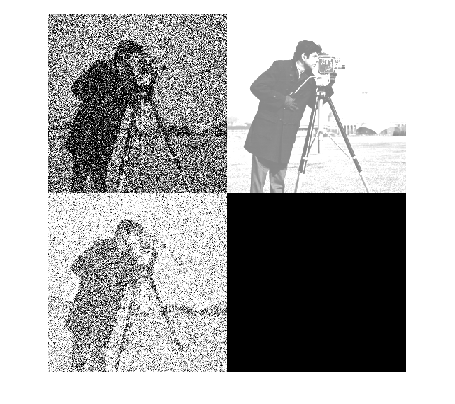

img = imread('cameraman.png');

J = imnoise(img,"gaussian",0,0.2);
K = imnoise(img,"gaussian",0.5,0.0);
L = imnoise(img,"gaussian",0.5,0.2);

J_fixed = wiener2(J, [11 11]);
K_fixed = wiener2(K, [11 11]);
L_fixed = wiener2(L, [11 11]);

montage({J,K,L})

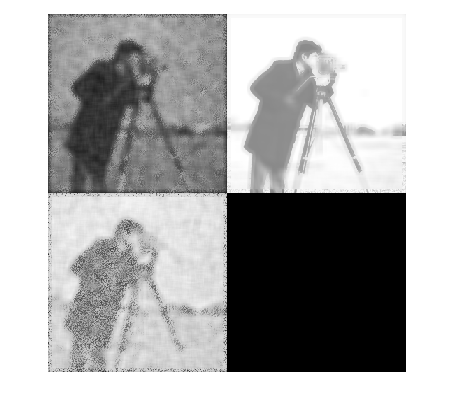

montage({J_fixed,K_fixed,L_fixed})